## МИУ 

MFIE - граничное условие для магнитного опля

#### H - поляризация

Сравнение нашего метода для MFIE с классическим MAS.

Сравнение проводиться с помощью вычитания токов 1го метода из токов другог и потом взятия по модулю.

16-02-21

close all;
clear variables;

## 1. Тестирование - предварительное

Сравним полученные данные, с данными расчитаными вручную. 

## 2. Главная часть скрипта

Задаем параметры эллипса и падающей волны 

a = 2; 
b = 1;
phi_grad = 60; 

Предположим мы получили невязку $10^{-14}$ для МВИ источников и выбрали количество источник N_mas_ref

N_mas_ref = 400;

Выбираем количество участков разибения N_comp для МИУ для 1-го графика

N_comp = 400;

Генерируем N_comp точки на элипсе X_comp, Z_comp.

% % Сгенерируем параметры элипса и упакуем их в структуру
% S = generate_elips_point(a,b,N_comp);
% 
% % параметры a,b и угол падения волны запишем в стр-ру - чтоб собой не таскать
% S.phi_grad = phi_grad;
% S.a = a;
% S.b = b;

Для этих точек (X_comp, Z_comp) в количества N_comp шт. считаем МВИ и получем токи I_ref (длиной N_comp)

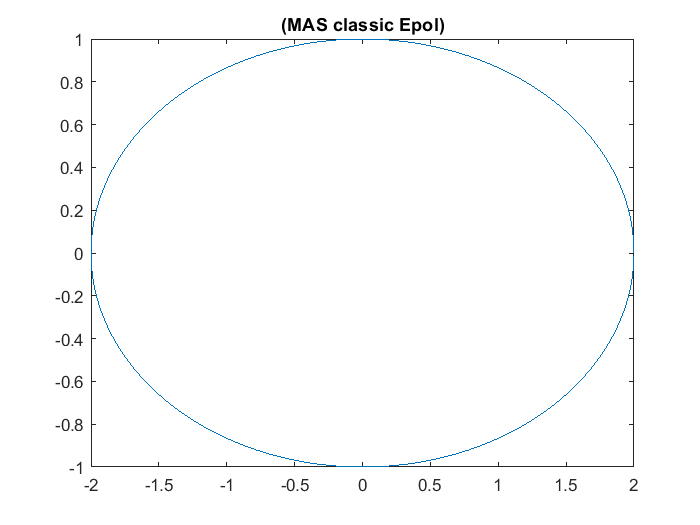

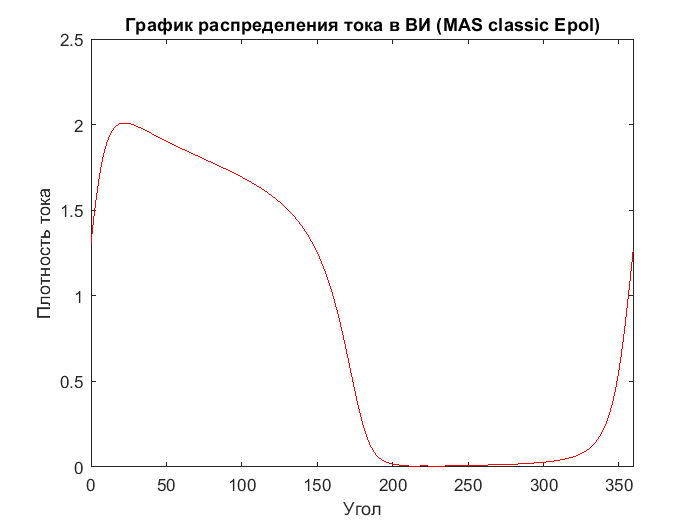

calc_ref = class_MAS_classic_Epol(a,b,phi_grad);
calc_ref.calculate_I(N_mas_ref,N_comp);

I_ref = calc_ref.get_I();  

Для этих точек (X_comp, Z_comp) в количества N_comp шт. считаем МИУ и получем токи I_comp (длиной N_comp)

Напомним что количество источников N_mas_ref, а количество точек на основном элипсе N_сomp

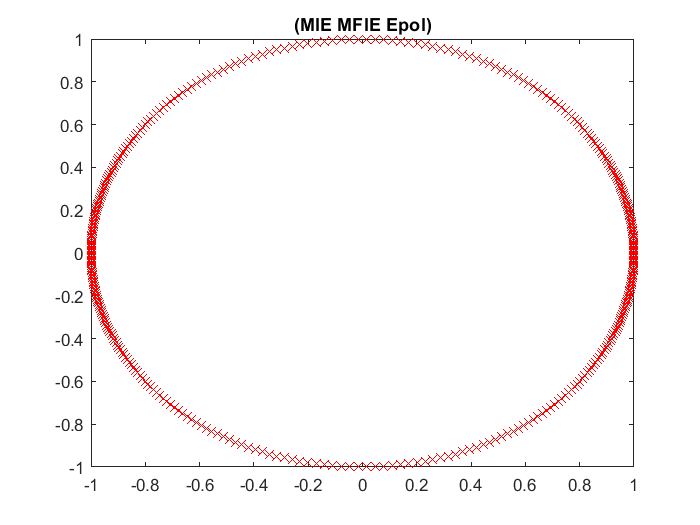

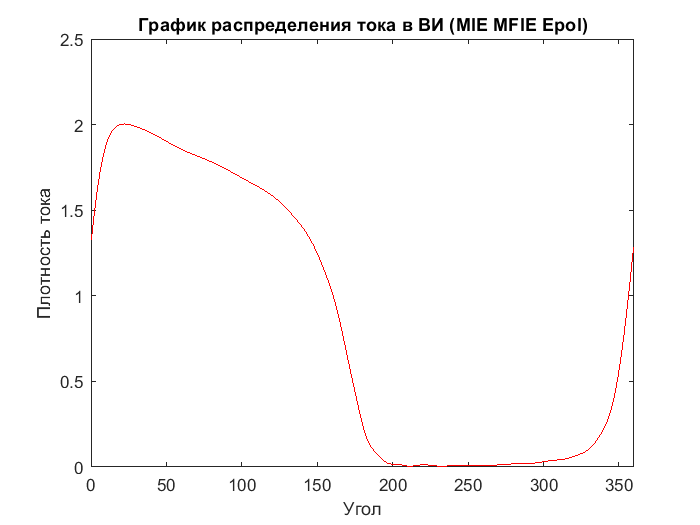

calc_comp = class_MIE_MFIE_E_pol(a,b,phi_grad);
calc_comp.calculate_I(N_comp);

I_comp = calc_comp.get_I();

Сравниваем токи и записываем в график 

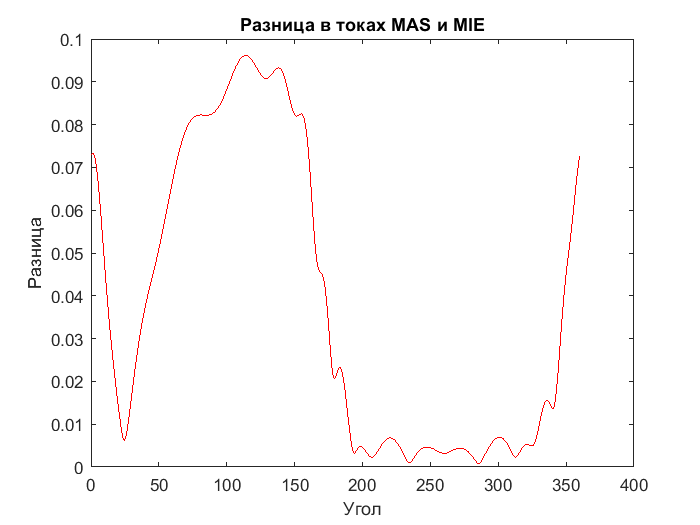

% разность токов
de_I = abs(I_ref + I_comp);

% распакуем рельные углы для графика из струкутры
phi_for_graf_real = calc_comp.phi_for_graf_real;

% построим график абсолютной разности токов
figure; 
plot(phi_for_graf_real, de_I,'r-');
title('Разница в токах MAS и MIE'); 
xlabel('Угол'); 
ylabel('Разница');

Запишем разницу токов в файл 

% % name_file = strcat('MFIE_MIE_Epol_compare_elips_',  num2str(N_comp), '.dat'); % в имея файла добавил число отрезков автоматом 
% % 
% % f01 = fopen(name_file,'w');
% % for n=1:N_comp
% %     fprintf(f01,' %10.5f %10.5f\n', phi_for_graf_real(n), de_I(n));
% % end
% % fclose(f01);

Посчитаем ЭПР МИУ MFIE

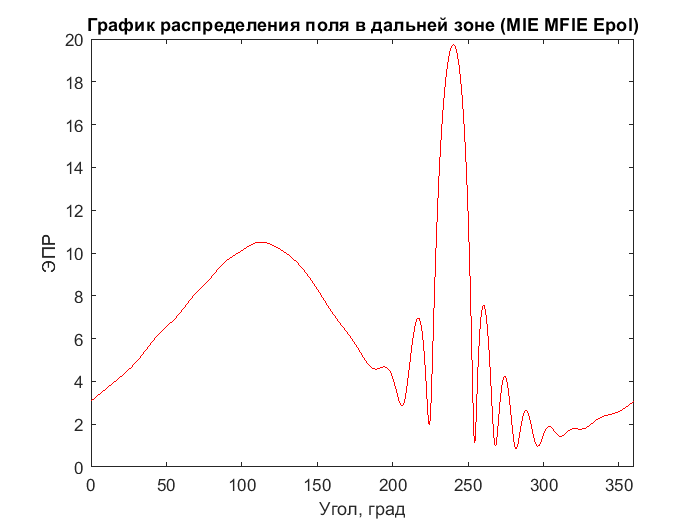

calc_comp.calculate_DA();

Sum_E_comp = calc_comp.Sum_E_mass;

Посчитаем ЭПР MAS 

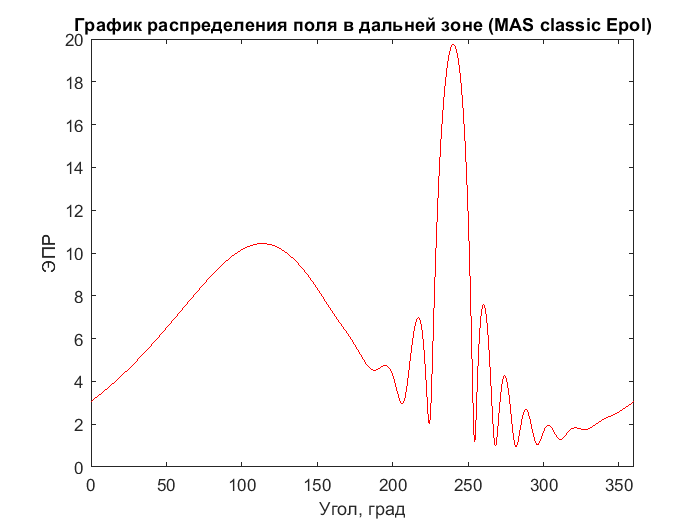

calc_ref.calculate_DA();

Sum_E_ref = calc_ref.Sum_E_mass;

Сравниваем ЭПР и записываем в график 

% разность cуммарных полей
de_Sum_E = Sum_E_ref - Sum_E_comp;

% расчет ЭПР
de_DA = zeros(length(de_Sum_E));
for i = 1 : length(de_Sum_E)
    de_DA(i) = 10*log10((2/pi)*de_Sum_E(i)*conj(de_Sum_E(i)));
end

% генератор углов для построения графика
phi_for_graf_DA = zeros(721,1);
for p = 1 : 721
    phi_for_graf_DA(p) = (p-1)/2;
end  
% построим график абсолютной разности ЭПР в дб
figure; 
plot(phi_for_graf_DA, de_DA,'r-');

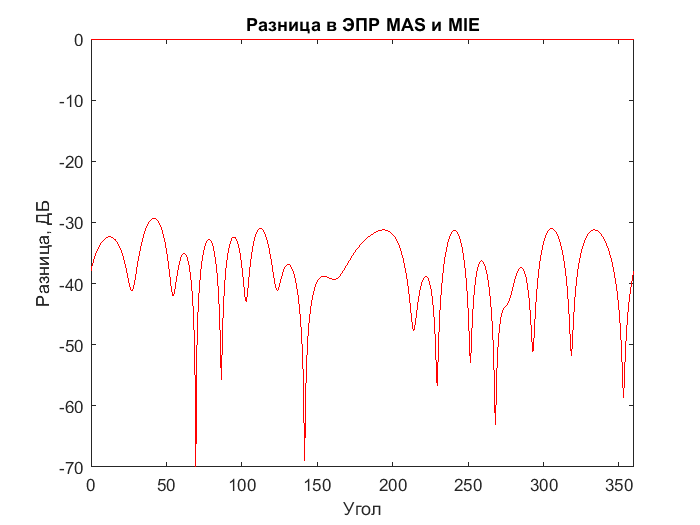

title('Разница в ЭПР MAS и MIE'); 
xlabel('Угол'); 
xlim([0 360]);
ylabel('Разница, ДБ');

Запишем разницу ЭПР в файл 

% name_file = strcat("DA_MFIE_MIE_Epol_compare_elips_", num2str(N_comp), '.dat'); % в имея файла добавил число отрезков автоматом 
% 
% f02 = fopen(name_file,'w');
% for n=1:length(de_DA)
%     fprintf(f02,' %10.5f %10.5f\n', phi_for_graf_DA(n), de_DA(n));
% end
% fclose(f02);